# Example 2: Analysis of an .stl file.

In this example, we will import and run various types of analysis on an stl file (provided with the toolbox).

## 2.1 Define the stl file and path for the file you wish to analyse

clearvars; clc; close;
filepathname = "data/stls/StanfordBunnySimplified.stl"; % Full name (and path) of the .stl file
MYMESH = surfaceMesh('stl',filepathname); % Create the surfaceMesh object from the .stl file

Calculate properties of the surfaceMesh object, define which method of curvature analysis you want to use.

"**none**" will produce the fastest result but have no curvature data - this is the default, and will be used for any other input.

"**trimesh2**" Is a generally accurate and stable method for triangulation meshes of standard objects, based on the paper: "Estimating Curvatures and Their Derivatives on Triangle Meshes", Szymon Rusinkiewicz 2004. And according to its C implementation 'trimesh2' for improved accuracy

"m**eyer2003**" uses the surfaceMesh curvature algorithm based on the paper:  Meyer, M., Desbrun, M., Schröder, P., & Barr, A. H. (2003). Discrete differential-geometry operators for triangulated 2-manifolds. Visualization and mathematics III (pp. 35-57). Springer Berlin Heidelberg. [http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.24.3427&rep=rep1&type=pdf](http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.24.3427&rep=rep1&type=pdf)

"**kroon**" uses the patch curvature function, written by D.Kroon University of Twente (August 2011) . This is based on a fitting a quadratic patch around each local vertex and it's neighbouring vertices. This is typically slower than the surfaceMeshcurvature algorithm.

"**implicit**" uses implicit differentiation, and is not avaliable for use with triangle meshes.

curvatureMethod = "trimesh2"; % Define which method of curvature analysis
MYMESH = MYMESH.calculateProperties(curvatureMethod);
faceProperties = fieldnames(MYMESH.Fproperty)

faceProperties = 8×1 cell array
    {'Zheight'     }
    {'Nx'          }
    {'Ny'          }
    {'Nz'          }
    {'Farea'       }
    {'Fvolume'     }
    {'Finclination'}
    {'Fazimuth'    }


vertexProperties = fieldnames(MYMESH.Vproperty)

vertexProperties = 16×1 cell array
    {'inclination'}
    {'Nx'         }
    {'Ny'         }
    {'Nz'         }
    {'azimuth'    }
    {'k1'         }
    {'k2'         }
    {'wfp'        }
    {'GC'         }
    {'MC'         }
    {'ABS'        }
    {'RMS'        }
    {'LPBFQuality'}
    {'Ra'         }
    {'Rz'         }
    {'LPBFerror'  }


quiverProperties = fieldnames(MYMESH.Qproperty)

quiverProperties = 3×1 cell array
    {'UnitNormal'}
    {'kDir1'     }
    {'kDir2'     }


## 2.2 Preview the a colored SurfaceMesh and data visualisation

Define the **property** you wish to preview. You may use any per-face or per-vertex property within **mySurfaceMesh**, the names of these properties may be found as the fields of **mysurfaceMesh.Fproperty** or **mySurfaceMesh.Vproperty **

You may specify to use "**fancy**" graphics, which will be used by default if nothing is specified.

You may also wish to pass in an **Axis**, which the surfaceMesh will be plotted on - by default a new axis will be created for the figure.

By default, the colorbar automatically scales to capture the 1st-99th percentile data.

property = 'MC'; % property name must match the string (anything after a blank space will be included for the label and not used for property selection)
qProperty = 'kDir1'

qProperty = 'kDir1'

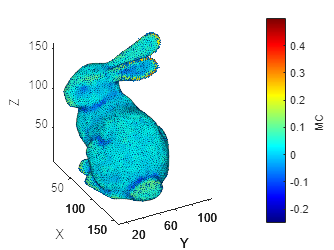

MYMESH.plotMesh(property,qProperty);

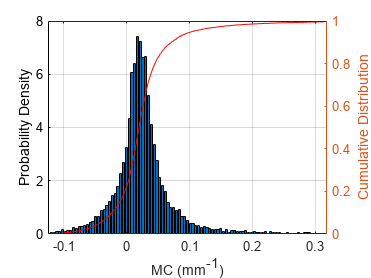


% Use a histogram to inspect distributions of a per-face or per-vertex
% property - for example look at the distribution of Mean curvature
property = 'MC (mm^-^1)'; % property name can include units which will be ignored for selecting propery, but be included in the plot label
plotHistogram(MYMESH,property);

## 2.3 Convert to field data structure

Field based, or implicit data is an alternative way to define geometry. The TPMS designer package includes utilities to convert a surfaceMesh object to a **v3field** object which is a voxelised representation of the same geometry.

The user may define a voxel size, smaller numbers will result in higher computational cost, but better resolution.

If you wish to create properties, this can be done by modifying the **v3field.calculateProperties** function and saving the new properties under v3field.properties. Note - this step may take some time to compute depending on the number of voxels in the mesh

voxelSize = 1.0; %voxelsize in mm
MYFIELD=MYMESH.getField(voxelSize); %F = v3Field(method,data,res,region,tform)
MYFIELD=MYFIELD.calculateProperties; % Call the calculate properties method to fill out property data
v3fieldnames = fieldnames(MYFIELD.property)

v3fieldnames = 7×1 cell array
    {'X'          }
    {'Y'          }
    {'Z'          }
    {'surface'    }
    {'solid'      }
    {'U'          }
    {'V3buildRisk'}


## 2.4 Preview and visualise field-based properties

Similarly to visualising property of a surfaceMesh, the user can visualise **v3field** properties.

You may specify a **sliceHeight** (as a percentage of the total object height) you with to preview the filed property at, this may be added/overlayed on previously made figures. Alternatively set **slice = 'orthoslice'** to utilise matlab's interactive orthosliceviewer.

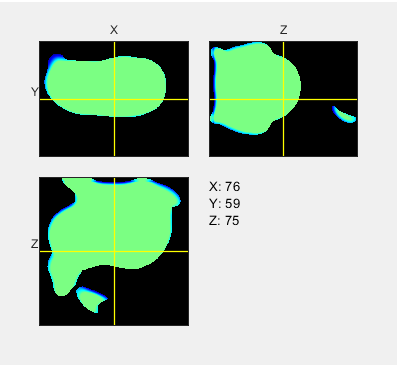

property = "V3buildRisk";
slice = 'orthoslice'; 
h = MYFIELD.plotField(property,slice);

## 2.5 Further Data Analysis

The distribution of various proeprties can also give inishgts into the performance of a component.

For example, we can look at the probability density distribution of the build risk index. The index is defined as nan=empty space, and solid volume ranging from 0 to 1 - where 0 has very little build risk, and 1 is likely to have problems/fail/need support.

A design which is more suited to additive manufacturing will have a distribution with a small fraction close to 1 (or volume which is requiring support structures).

temp = MYFIELD.property.V3buildRisk;
temp = temp(MYFIELD.property.surface==1);
histogram(temp,'BinLimits',[0 1],'Normalization',"pdf");
ylabel(gca,'Probability Density'); xlabel(gca,property);

## 2.6 Using metrics to compare different objects

As the structures investigated are highly complex and are often unwieldy to asses, TPMS Designer utilises a metrics-based approach. This allows a property of a complex design to be approximated with a simplified metric - these are used heavily in **example3_DOE** to compare various properties of TPMS-like structure in a large design of experiments. 

The **metrics** class includes a predefined set of normalised sums, means, maximums or defined percentiles value of various properties, as well as some mechanical metrics for use in comparing cellular structures.

Different metrics may require different properties to be calculated for the field or surface-mesh based representation of an object.

Many of the metrics are designed specifically for a unit-cell of a periodic structure (like a TPMS), so these values will have little meaning - such as volumeFraction or be left uncalculated such as the totalStiffness.

M = metrics;
M = M.fvMetrics(MYMESH);
M = M.mechanicalMetrics(MYFIELD)

M =   metrics with properties:

           CPUtime: []
            Nfaces: 20480
            Nnodes: 10242
         errorFlag: 0
        meshVolume: 6.7582e+05
    relativeVolume: 0.2694
       surfaceArea: 5.1720e+04
      relativeArea: []
             rmsMC: 0.0555
             rmsGC: 0.0053
         thickness: 80.5101
      poreDiameter: 96.9793
       thicknessAM: 40.2089
           areaVar: 0.0306
          areaMean: 0.2635
           areaStd: 0.1750
           areaMin: 0
           areaMax: 0.5006
           elastic: []
           poisson: []
             shear: []
    totalStiffness: []
        zenerRatio: []
